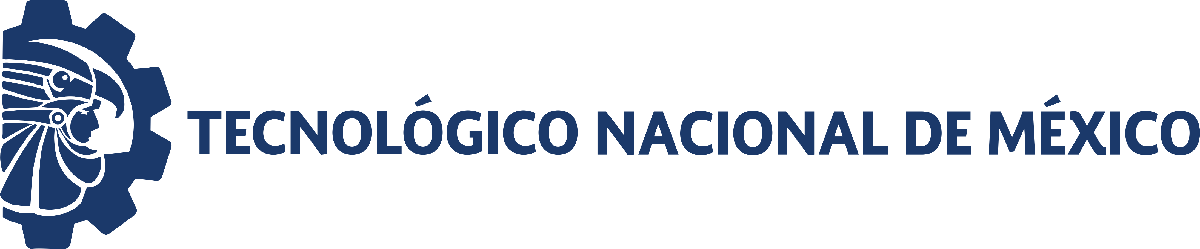                                 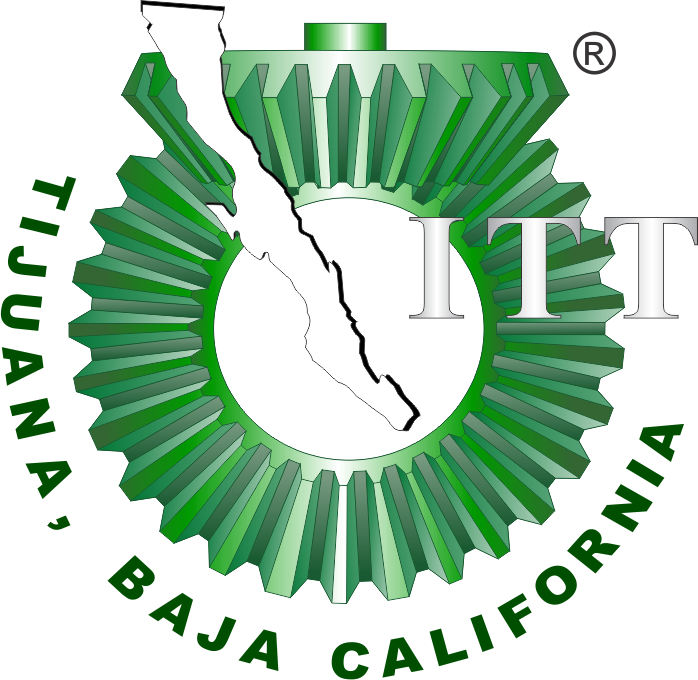

# Proyecto Final

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

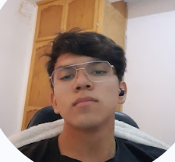

Nombre del alumno: **Chaparro Zamora Alain Yahir**

Número de control: **21212147**

Correo institucional: **l21212147@tectijuana.edu.mx**

Carrera:** Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

**Objetive: **To integrate specific competencies related to the modeling, analysis, and control of biological systems, in order to illustrate and predict their dynamics in both the short and long term. The goal is to lay the groundwork for the development of digital twins capable of addressing and solving problems within the field of Systems Biology.

## Simulation Data

    tiempo    x1(t)    y1(t)     Z1(t)
    ______    _____    ______    _____

       0      0.517    19.939    0.281
       7       0.58    19.578    0.609
      14      0.726    18.678    1.063
      21      0.965    16.215    1.758
      28      1.282    14.005    2.752
      35      1.825    11.467    3.975
      42      2.473     8.096    4.895
      49      2.974     4.327    6.096
      56       3.43     1.287    7.152
      63      3.717     0.194    7.328
      70      3.829      0.56    7.232



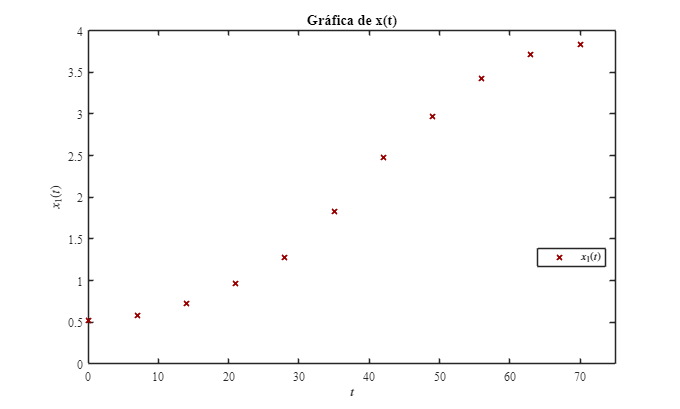

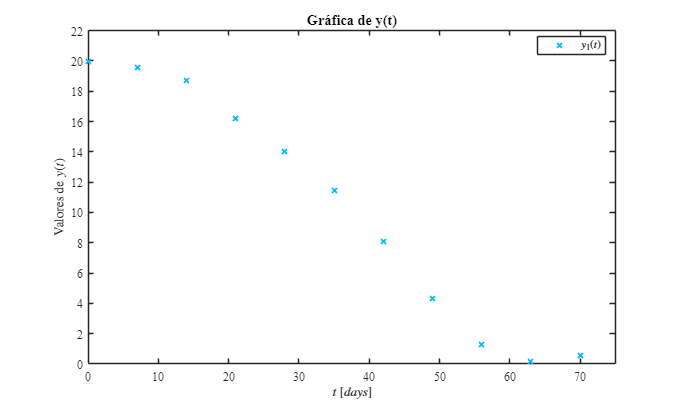

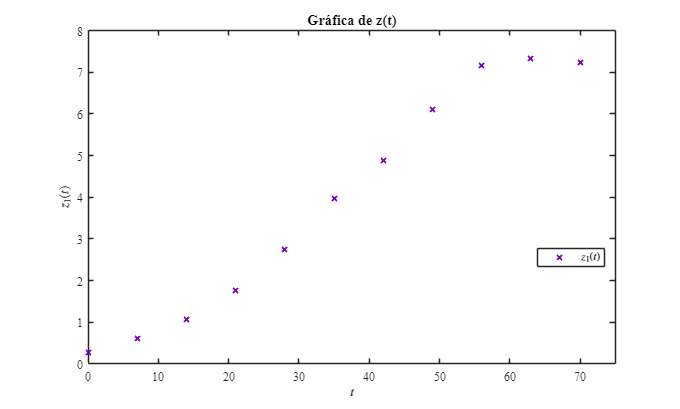

clc; clear; close all; warning('off','all')
filename = 'data.csv';
sys = readmatrix(filename);
to = sys(:,1);
x1 = sys(:,2);
y1 = sys(:,3);
Z1 = sys(: ,4);
T = array2table([to, x1,y1,Z1], 'VariableNames', {'tiempo', 'x1(t)', 'y1(t)', 'Z1(t)'});
disp(T); plotdata(to, x1, y1, Z1)

## Smooth Data

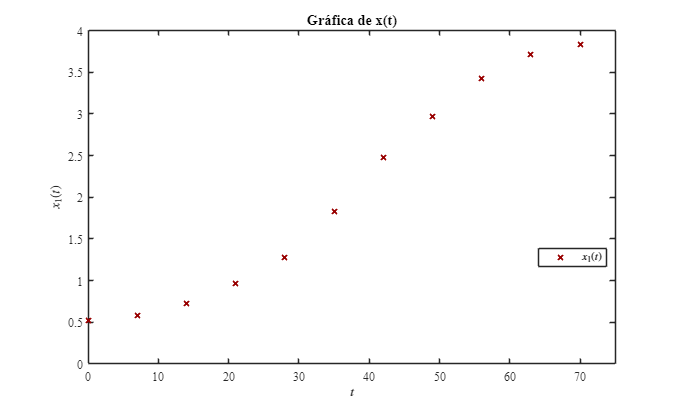

Datos suavizados (misma cantidad de puntos) exportados como "data_fit.csv".


clc; clear; close all; warning('off','all')
filename = 'Data.csv';
sys = readmatrix(filename);
to= sys(:,1);
xo= sys(:,2);
yo= sys(:,3);
zo= sys(:,4);
plotDataS(to, xo, yo, zo);

## Nonlinear Regression

##  

##  

##  


Sample size (n): 11
Parameters to be estimated: 6
Degrees of freedom: 27
R-squared: 0.9998
Corrected AIC: -65.2787

    Param     Estimate         SE           MoE                  CI95                pValue  
    _____    __________    __________    __________    ________________________    __________

    "p1"      0.0006015    9.2161e-05     0.0001891    0.00041241     0.0007906    5.3482e-07
    "p2"     0.00072444    3.8939e-05    7.9896e-05    0.00064454    0.00080434    6.3191e-17
    "p3"       0.014804    0.00042563    0.00087331      0.013931      0.015677    5.8103e-24
    "p4"       0.030033    0.00055695     0.0011428       0.02889      0.031176     4.956e-29
    "p5"      0.0040202    0.00067335     0.0013816     0.0026386     0.0054018    2.2873e-06
    "p6"      0.0029

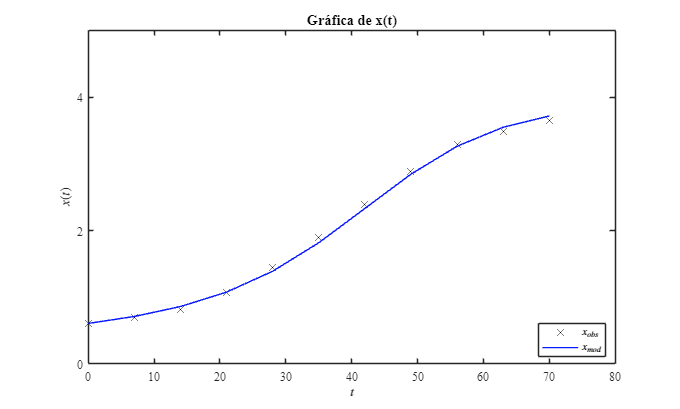

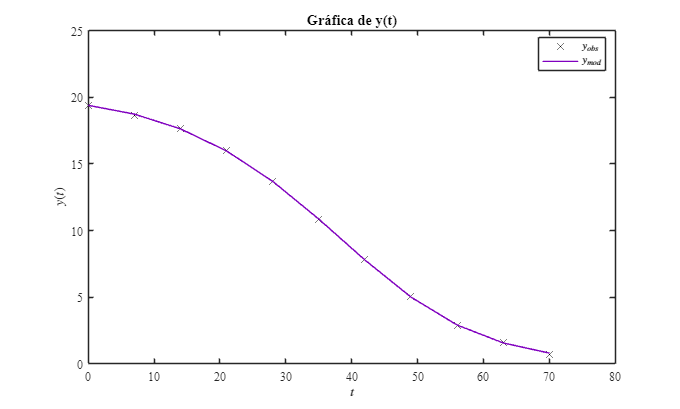

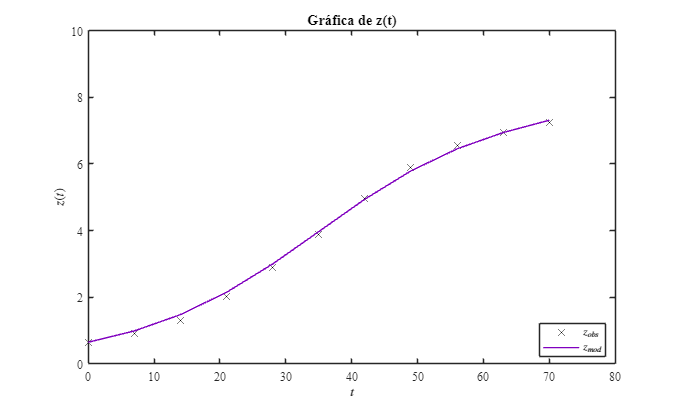

warning('off')
sys = readmatrix('data_fit.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
zo = sys(:,4);
P0 = [0.0012; 0.00055; 0.013; 0.028; 0.0020; 0.0033];
[mdl, xa, ya, za] = Varied(to, xo, yo, zo, P0);

## Jacobian Matrix

clear; close all; clc
syms xo yo zo p1 p2 p3 p4 p5 p6 real
dx = p1*xo*yo + p2*xo*yo*zo;
dy = p3*yo - p4*xo*yo;
dz = p5*zo + p6*yo*zo;
J = jacobian([dx, dy, dz], [xo, yo, zo]);
disp('Jacobian matrix of the system:'); disp(J);

Jacobian matrix of the system:


$$\left(\begin{array}{ccc} p_{1}\,\mathrm{yo}+p_{2}\,\mathrm{yo}\,\mathrm{zo} & p_{1}\,\mathrm{xo}+p_{2}\,\mathrm{xo}\,\mathrm{zo} & p_{2}\,\mathrm{xo}\,\mathrm{yo}\\ -p_{4}\,\mathrm{yo} & p_{3}-p_{4}\,\mathrm{xo} & 0\\ 0 & p_{6}\,\mathrm{zo} & p_{5}+p_{6}\,\mathrm{yo} \end{array}\right)$$

## Equilibrium points

clear; close all; clc
syms xo yo zo p1 p2 p3 p4 p5 p6 real
dx = p1*xo*yo + p2*xo*yo*zo;
dy = p3*yo - p4*xo*yo;
dz = p5*zo + p6*yo*zo;
eq1 = dx == 0;
eq2 = dy == 0;
eq3 = dz == 0;
edos = solve([eq1, eq2, eq3], [xo, yo, zo], 'Real', true);
n = length(edos.xo);
fprintf('The system has %d equilibrium point(s).\n\n', n);

The system has 2 equilibrium point(s).



for i = 1:min(2,n)
fprintf('Equilibrium point %d:\n', i);
fprintf('xo = %s\n', char(edos.xo(i)));
fprintf('yo = %s\n', char(edos.yo(i)));
fprintf('zo = %s\n\n', char(edos.zo(i)));
end

Equilibrium point 1:


xo = 0


yo = 0


zo = 0



Equilibrium point 2:


xo = p3/p4


yo = -p5/p6


zo = -p1/p2



## 2tMax

warning('off')
sys = readmatrix('data_fit.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
zo = sys(:,4);
P0 = [0.0012; 0.00055; 0.013; 0.028; 0.0020; 0.0033];
[mdl, xa, ya, za, t_ext, x_ext, y_ext, z_ext] = VariedExtended(to, xo, yo, zo, P0);


[EXTENDED] Sample size (n): 11
Parameters to be estimated: 6
Degrees of freedom: 27
R-squared: 0.9998
Corrected AIC: -65.2787

    Param     Estimate         SE           MoE                  CI95                pValue  
    _____    __________    __________    __________    ________________________    __________

    "p1"      0.0006015    9.2161e-05     0.0001891    0.00041241     0.0007906    5.3482e-07
    "p2"     0.00072444    3.8939e-05    7.9896e-05    0.00064454    0.00080434    6.3191e-17
    "p3"       0.014804    0.00042563    0.00087331      0.013931      0.015677    5.8103e-24
    "p4"       0.030033    0.00055695     0.0011428       0.02889      0.031176     4.956e-29
    "p5"      0.0040202    0.00067335     0.0013816     0.0026386     0.0054018    2.2873e-06
    "p6" 

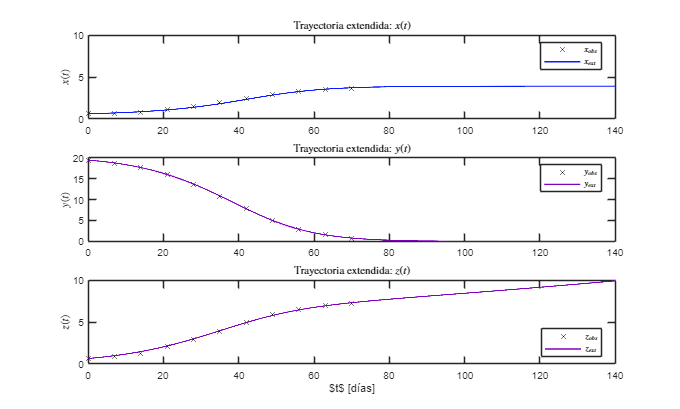

plot2t(to, xo, yo, zo, t_ext, x_ext, y_ext, z_ext);

## **Representation**

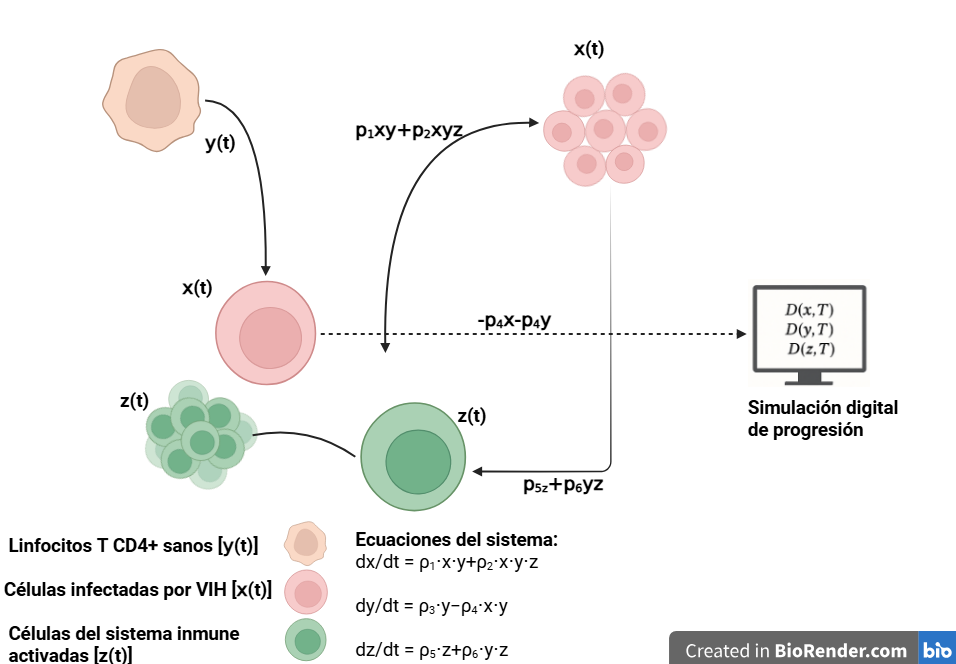

The diagram illustrates a dynamic model of HIV infection, developed from in vitro experimental data. The system is composed of three interacting immune cell populations:

- Normal Cells y(t): CD4+ T cells not yet infected.

- Infected Cells x(t): CD4+ T cells that have been infected.

- Immune System Cells z(t): Activated effector cells (e.g., CD8+ cytotoxic T lymphocytes).

Arrows between the cell types represent biological interactions expressed through nonlinear mathematical terms formulated as differential equations. These expressions describe the rate of change of each population over time, using symbolic parameters rho_1 through rho_6, which represent different biological interaction rates.

For example:

- The infection process is modeled by the interaction term rho_1xy, and it is further influenced by the immune system through rho_2xyz.

- The immune response is described by the activation of immune cells via intrinsic growth (rho_5z) and stimulation by healthy cells (rho_6yz).

- The loss of healthy cells due to infection is modeled by the term -rho_4xy, while their natural proliferation is given by rho_3y.

On the right side, the diagram includes a digital twin simulation block, representing the system of differential equations:

dx/dt = rho_1xy+rho_2xyz

dy/dt = rho_3y-rho_4xy

dz/dt = rho_5z+rho_6yz

This simulation-based model enables the prediction of system dynamics over time and supports the exploration of long-term behavior and stability under controlled computational conditions, without requiring specific clinical assumptions.

## Conclussions

The present work involved the construction, simulation, and evaluation of a nonlinear dynamic model aimed at capturing the behavior of a physiological system composed of three interrelated variables over time. The modeling process was data-driven, relying entirely on time-series experimental values collected over a period of 63 days, and did not assume any prior biological or clinical context regarding the meaning of each variable. The differential equations were formulated to describe how each variable changes with respect to time, incorporating six interaction parameters. These parameters were estimated using nonlinear regression, based on smoothed versions of the original dataset to reduce the effects of measurement noise and discontinuities.

One of the most relevant outcomes of the model fitting was the **extremely high coefficient of determination (R² = 0.9998)**, which confirms that the system of equations captures the observed behavior of the data with remarkable precision. Additionally, the model's **corrected Akaike Information Criterion (AICc = –65.28)** further supports the adequacy of the model structure, balancing goodness of fit and model complexity. Each of the six estimated parameters was found to be **statistically significant**, with *p*-values approaching zero, and their confidence intervals were sufficiently narrow. This suggests that all components of the equations contribute meaningfully to the modeled dynamics. Moreover, the model does not rely on redundant or unnecessary terms, which is critical for interpretability and future generalization.

The **Jacobian matrix analysis** revealed insight into the system's local sensitivity and interdependence between variables. Furthermore, the identification of **two equilibrium points**, including one non-trivial fixed point with non-zero variable values, indicates that the system tends toward stability under specific conditions. These equilibrium states are useful for characterizing long-term behavior and can serve as references for future stability analysis or control strategies. A significant contribution of the study was the implementation of an **extended simulation (2T model)**, in which the model was used to forecast the behavior of the system for a time span twice as long as the original dataset. The results of this extended projection revealed that the model behaves in a stable and consistent manner outside the initial data window. No abrupt divergences or unrealistic trends were observed, which supports the idea that the equations are not only descriptive but also predictive within a reasonable time frame. Another valuable result was the visual comparison between the observed data, the smoothed data, and the simulated outputs. These graphs confirmed that the model tracks the expected trajectories effectively, preserving key dynamics such as exponential growth, decay, saturation, or delayed responses between variables.

Finally, the methodology developed in this work—from data preprocessing and curve fitting to mathematical formulation and simulation—demonstrates the **potential of mathematical modeling in representing physiological systems** without the need for detailed domain knowledge at the early stages. This kind of abstraction is particularly useful when the goal is to analyze system-level behaviors, test structural hypotheses, or prepare a base model that can later be contextualized or personalized with additional biological or clinical information.

## Function

## Raw data plot

function plotdata(t, x, y, z)
    % Tres colores definidos manualmente
    c1 = [0.60, 0.00, 0.00];  % Rojo oscuro
    c2 = [0.00, 0.75, 1.00];  % Azul claro
    c3 = [0.50, 0.00, 0.75];  % Púrpura

    % Gráfica para x(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, x, 'x', 'LineWidth', 1.5, 'Color', c1, 'DisplayName', '$x_1(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$x_1(t)$', 'Interpreter', 'latex')
    xlim([0 75])
    xticks(0:10:75)
    ylim([0 4])
    yticks(0:0.5:4)
    title('Gráfica de x(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para y(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [24, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, y, 'x', 'LineWidth', 1.5, 'Color', c2, 'DisplayName', '$y_1(t)$')
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('Valores de $y(t)$', 'Interpreter', 'latex')
    xlim([0 75])
    xticks(0:10:75)
    ylim([0 22])
    yticks(0:2:22)
    title('Gráfica de y(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para z(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [46, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, z, 'x', 'LineWidth', 1.5, 'Color', c3, 'DisplayName', '$z_1(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$z_1(t)$', 'Interpreter', 'latex')
    xlim([0 75])
    xticks(0:10:75)
    ylim([0 8])
    yticks(0:1:8)
    title('Gráfica de z(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')
end



## Smooth data plot

function plotDataS(t, x, y, z)
    % Tres colores definidos manualmente
    c1 = [0.60, 0.00, 0.00];  % Rojo oscuro
    c2 = [0.00, 0.75, 1.00];  % Azul claro
    c3 = [0.50, 0.00, 0.75];  % Púrpura

    % Suavizado real (mantiene misma cantidad de puntos)
    x_s = smoothdata(x, 'movmean', 5);
    y_s = smoothdata(y, 'movmean', 5);
    z_s = smoothdata(z, 'movmean', 5);

    % Crear figura única
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 5, 18, 15]);

      % Gráfica para x(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, x, 'x', 'LineWidth', 1.5, 'Color', c1, 'DisplayName', '$x_1(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$x_1(t)$', 'Interpreter', 'latex')
    xlim([0 75])
    xticks(0:10:75)
    ylim([0 4])
    yticks(0:0.5:4)
    title('Gráfica de x(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para y(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [24, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, y, 'x', 'LineWidth', 1.5, 'Color', c2, 'DisplayName', '$y_1(t)$')
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('Valores de $y(t)$', 'Interpreter', 'latex')
    xlim([0 75])
    xticks(0:10:75)
    ylim([0 22])
    yticks(0:2:22)
    title('Gráfica de y(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para z(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [46, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, z, 'x', 'LineWidth', 1.5, 'Color', c3, 'DisplayName', '$z_1(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$z_1(t)$', 'Interpreter', 'latex')
    xlim([0 75])
    xticks(0:10:75)
    ylim([0 8])
    yticks(0:1:8)
    title('Gráfica de z(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Exportar datos suavizados con misma cantidad de puntos
    datos_fit = table(t(:), x_s(:), y_s(:), z_s(:), ...
        'VariableNames', {'T', 'x', 'y', 'z'});
    writetable(datos_fit, 'data_fit.csv');
    disp('Datos suavizados (misma cantidad de puntos) exportados como "data_fit.csv".');
end



## Nonlinear regression algorithm

function [mdl, xa, ya, za] = Varied(to, xo, yo, zo, P0)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to3 = [to; to; to];
    fo = [xo; yo; zo];

    function fi = model(p, tvec)
        dt = 0.01;
        tmat = reshape(tvec, [], 3);
        t = tmat(:,1);
        time = (0:dt:max(t))';
        n = numel(time);

        x = zeros(n,1); x(1) = x0;
        y = zeros(n,1); y(1) = y0;
        z = zeros(n,1); z(1) = z0;

        for i = 1:n-1
            [dx, dy, dz] = f(x(i), y(i), z(i), p);
            xp = x(i) + dx*dt;
            yp = y(i) + dy*dt;
            zp = z(i) + dz*dt;
            [dxp, dyp, dzp] = f(xp, yp, zp, p);

            x(i+1) = x(i) + (dx + dxp)*dt/2;
            y(i+1) = y(i) + (dy + dyp)*dt/2;
            z(i+1) = z(i) + (dz + dzp)*dt/2;
        end

        xi = interp1(time, x, t, 'linear', NaN);
        yi = interp1(time, y, t, 'linear', NaN);
        zi = interp1(time, z, t, 'linear', NaN);

        fi = [xi; yi; zi];
    end

    function [dx, dy, dz] = f(x, y, z, p)
        % Nuevas ecuaciones con 6 parámetros
        dx = p(1)*x*y + p(2)*x*y*z;
        dy = p(3)*y - p(4)*x*y;
        dz = p(5)*z + p(6)*y*z;
    end

    mdl = fitnlm(to3, fo, @model, P0);

    fa = mdl.Fitted;
    fn = reshape(fa, [], 3);
    xa = fn(:,1);
    ya = fn(:,2);
    za = fn(:,3);

    coef = mdl.Coefficients;
    Estimate = coef.Estimate;
    SE = coef.SE;
    pValue = coef.pValue;
    CI95 = coefCI(mdl, 0.05);
    dof = mdl.DFE;
    tval = tinv(0.975, dof);
    MoE = SE * tval;
    Params = ["p1"; "p2"; "p3"; "p4"; "p5"; "p6"];
    Results = table(Params, Estimate, SE, MoE, CI95, pValue, ...
        'VariableNames', {'Param','Estimate','SE','MoE','CI95','pValue'});

    fprintf('\nSample size (n): %d', numel(xo));
    fprintf('\nParameters to be estimated: %d', numel(P0));
    fprintf('\nDegrees of freedom: %d', dof);
    fprintf('\nR-squared: %.4f', mdl.Rsquared.Ordinary);
    fprintf('\nCorrected AIC: %.4f\n\n', mdl.ModelCriterion.AICc);
    disp(Results);

    X_plot = [xo, xa];
    Y_plot = [yo, ya];
    Z_plot = [zo, za];
    plotXYZResults(to, X_plot, Y_plot, Z_plot);
end



## Nonlinear regression plot

function plotXYZResults(t, X, Y, Z)
    % Colores fijos
    negro  = [0.00, 0.00, 0.00];
    azul   = [0.04, 0.10, 1.00];
    morado = [0.50, 0.00, 0.75];

    % --------- Figura para x(t) ---------
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on;
    plot(t, X(:,1), 'x', 'Color', negro, 'MarkerSize', 8, 'DisplayName', '$x_{obs}$')
    plot(t, X(:,2), '-', 'Color', azul, 'LineWidth', 1.2, 'DisplayName', '$x_{mod}$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$x(t)$', 'Interpreter', 'latex')
    title('Gráfica de x(t)', 'Interpreter', 'latex', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')
    xlim([0 80]); ylim([0 5])
    xticks(0:10:80); yticks(0:2:5)

    % --------- Figura para y(t) ---------
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 16, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on;
    plot(t, Y(:,1), 'x', 'Color', negro, 'MarkerSize', 8, 'DisplayName', '$y_{obs}$')
    plot(t, Y(:,2), '-', 'Color', morado, 'LineWidth', 1.2, 'DisplayName', '$y_{mod}$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$y(t)$', 'Interpreter', 'latex')
    title('Gráfica de y(t)', 'Interpreter', 'latex', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')
    xlim([0 80]); ylim([0 25])
    xticks(0:10:80); yticks(0:5:25)

    % --------- Figura para z(t) ---------
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 30, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on;
    plot(t, Z(:,1), 'x', 'Color', negro, 'MarkerSize', 8, 'DisplayName', '$z_{obs}$')
    plot(t, Z(:,2), '-', 'Color', morado, 'LineWidth', 1.2, 'DisplayName', '$z_{mod}$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$z(t)$', 'Interpreter', 'latex')
    title('Gráfica de z(t)', 'Interpreter', 'latex', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')
    xlim([0 80]); ylim([0 10])
    xticks(0:10:80); yticks(0:2:10)
end



## 2T model

function [mdl, xa, ya, za, t_ext, x_ext, y_ext, z_ext] = VariedExtended(to, xo, yo, zo, P0)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to3 = [to; to; to];
    fo = [xo; yo; zo];

    function fi = model(p, tvec)
    dt = 0.01;
    tmat = reshape(tvec, [], 3);
    t = tmat(:,1);

    TMAX = 2 * max(to);             % <- aseguramos que llega a 140
    time = (0:dt:TMAX)';            % <- tiempo extendido definido

    n = numel(time);
    x = zeros(n,1); x(1) = x0;
    y = zeros(n,1); y(1) = y0;
    z = zeros(n,1); z(1) = z0;

    for i = 1:n-1
        [dx, dy, dz] = f(x(i), y(i), z(i), p);
        xp = x(i) + dx*dt;
        yp = y(i) + dy*dt;
        zp = z(i) + dz*dt;
        [dxp, dyp, dzp] = f(xp, yp, zp, p);

        x(i+1) = x(i) + (dx + dxp)*dt/2;
        y(i+1) = y(i) + (dy + dyp)*dt/2;
        z(i+1) = z(i) + (dz + dzp)*dt/2;
    end

    assignin('base', 't_ext', time);
    assignin('base', 'x_ext', x);
    assignin('base', 'y_ext', y);
    assignin('base', 'z_ext', z);

    xi = interp1(time, x, t, 'linear', NaN);
    yi = interp1(time, y, t, 'linear', NaN);
    zi = interp1(time, z, t, 'linear', NaN);

    fi = [xi; yi; zi];
end


    function [dx, dy, dz] = f(x, y, z, p)
        dx = p(1)*x*y + p(2)*x*y*z;
        dy = p(3)*y - p(4)*x*y;
        dz = p(5)*z + p(6)*y*z;
    end

    mdl = fitnlm(to3, fo, @model, P0);

    fa = mdl.Fitted;
    fn = reshape(fa, [], 3);
    xa = fn(:,1);
    ya = fn(:,2);
    za = fn(:,3);

    coef = mdl.Coefficients;
    Estimate = coef.Estimate;
    SE = coef.SE;
    pValue = coef.pValue;
    CI95 = coefCI(mdl, 0.05);
    dof = mdl.DFE;
    tval = tinv(0.975, dof);
    MoE = SE * tval;
    Params = ["p1"; "p2"; "p3"; "p4"; "p5"; "p6"];
    Results = table(Params, Estimate, SE, MoE, CI95, pValue, ...
        'VariableNames', {'Param','Estimate','SE','MoE','CI95','pValue'});

    fprintf('\n[EXTENDED] Sample size (n): %d', numel(xo));
    fprintf('\nParameters to be estimated: %d', numel(P0));
    fprintf('\nDegrees of freedom: %d', dof);
    fprintf('\nR-squared: %.4f', mdl.Rsquared.Ordinary);
    fprintf('\nCorrected AIC: %.4f\n\n', mdl.ModelCriterion.AICc);
    disp(Results);

    X_plot = [xo, xa];
    Y_plot = [yo, ya];
    Z_plot = [zo, za];

    % Retornar también la trayectoria extendida
    t_ext = evalin('base', 't_ext');
    x_ext = evalin('base', 'x_ext');
    y_ext = evalin('base', 'y_ext');
    z_ext = evalin('base', 'z_ext');
end

## 2T plot

function plot2t(to, xo, yo, zo, t_ext, x_ext, y_ext, z_ext)
    % Colores fijos
    negro  = [0.00, 0.00, 0.00];
    azul   = [0.04, 0.10, 1.00];
    morado = [0.50, 0.00, 0.75];

    % Crear figura
    figure('Color', 'w', 'Units', 'centimeters', 'Position', [2, 2, 20, 12]);

    % Subplot x(t)
    subplot(3,1,1)
    hold on; box on;
    plot(to, xo, 'x', 'Color', negro, 'DisplayName', '$x_{obs}$');
    plot(t_ext, x_ext, '-', 'Color', azul, 'LineWidth', 1.2, 'DisplayName', '$x_{ext}$');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim([0 max(t_ext)]); ylim([0 10]);
    legend('Interpreter', 'latex', 'Location', 'best');
    title('Trayectoria extendida: $x(t)$', 'Interpreter', 'latex');

    % Subplot y(t)
    subplot(3,1,2)
    hold on; box on;
    plot(to, yo, 'x', 'Color', negro, 'DisplayName', '$y_{obs}$');
    plot(t_ext, y_ext, '-', 'Color', morado, 'LineWidth', 1.2, 'DisplayName', '$y_{ext}$');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 max(t_ext)]); ylim([0 20]);
    legend('Interpreter', 'latex', 'Location', 'best');
    title('Trayectoria extendida: $y(t)$', 'Interpreter', 'latex');

    % Subplot z(t)
    subplot(3,1,3)
    hold on; box on;
    plot(to, zo, 'x', 'Color', negro, 'DisplayName', '$z_{obs}$');
    plot(t_ext, z_ext, '-', 'Color', morado, 'LineWidth', 1.2, 'DisplayName', '$z_{ext}$');
    xlabel('$t$ [días]', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    xlim([0 max(t_ext)]); ylim([0 10]);
    legend('Interpreter', 'latex', 'Location', 'best');
    title('Trayectoria extendida: $z(t)$', 'Interpreter', 'latex');
end
